# Level Control of a Two Tank System: Case study

Level control in a two tank system is investigated. The model of the system is given by the physical equations describing its behaviour. The model is nonlinear. In order to handle easier the level control, the model is linearised around the working points. The aim is to control the level of the lower tank. The manipulating variable is the input flow in the upper tank. PI(D) control is designed and applied to the system.

Readers should note that the partner virtual laboratory ***twotanks.mlapp*** assumes only linearised models and does not use  the Simulink files and non-linear models discussed below, but does allow users to explore the control and behaviour issues in a simple interactive environment.

We assume users are familiar with the basic analysis tools such as covered in ***plotting_with_matlab.mlx, *** ***transferfunctions_and_poles.mlx,*** ***step_responses_with_matlab.mlx and, effects_of_negative_feedback.mlx ***and also with methods of tuning PI(D) controllers, discussed in files ***PI(D) controller design PID_tuning_methods.mlx,*** ***PID_Cont_Controller_Design_with_Pole_Cancellation.mlx***.

Dynamics of one tank system and its level control is discussed in files ***tanklevel_story.mlx,*** ***tanklevelbehaviour.mlx*** and ***tanklevel_and_PI_control.mlx***.

This live script needs the control toolbox.

### Similar files and the toolbox

See website below for more files like this.   [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Ruth Bars and Gyula Max                   minor edits by J.A.Rossiter, University of Sheffield

Budapest University of Technology and Economics                                                 

                                 

## Table of contents

- Scheme of the two tank system

- The mathematical model of the two tank system

- Linearisation of the model

- Transfer function of the linearised two-tank model

- Simulating the behaviour of the nonlinear two-tank system

- Simulink model of the two tank system

- Calculation of the parameters of the linearised model

- PI(D) control of the two tank system

- Useful subfunctions

## 1.Scheme of the two tank system

The scheme of the system is given in Fig.1. The inlet water quantity is denoted by $u_1$, the outlet water outflow quantities are  $y_1$ and $y_2$ respectively. The water levels are denoted by $h_1$ and $h_2$. The cross sections of the tanks are $A_1$ and $A_2$. The cross sections of the outlet tubes are denoted by "a". 

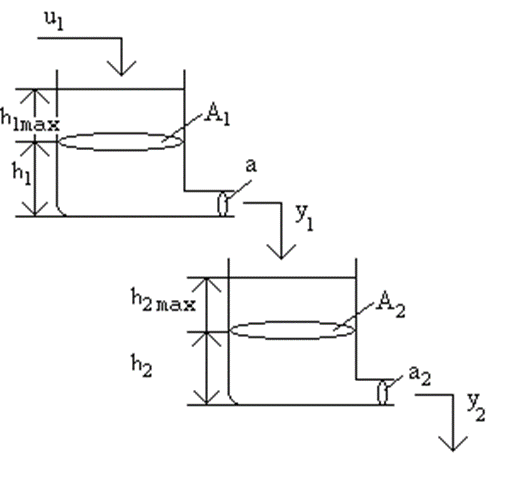

                                   Figure 1. The scheme of the two tank systems

## 2. The mathematical model of the two tank system

The mathematical model of the plant can be derived understanding its behaviour and describing it by mathematical relationships.

From the balance of the potential energy and the motion energy the velocity of the outlet water is obtained as


$$\textrm{mg}h_1 =\frac{1}{2}mv_1^2$$


hence

$v_1 =\sqrt{2gh_1 }$  and  

$y_1 =\mu av_1 =\mu a\sqrt{2g}\sqrt{h_1 }=k_1 \sqrt{h_1 }$,  where $\mu$ is the viscosity factor.

The changes in the levels in the two tanks can be written as


$$\frac{dh_1 }{\textrm{dt}}=\frac{u_1 -y_1 }{A_1 }=\frac{1}{A_1 }u_1 -\frac{k_1 }{A_1 }\sqrt{h_1 }$$



$$\frac{dh_2 }{\textrm{dt}}=\frac{1}{A_2 }\left(k_1 \sqrt{h_1 }-k_2 \sqrt{h_2 }\right)$$


Let us introduce the relative units

$h_{\textrm{rel}} =\frac{h}{h_{\max } }$  and  $u_{\textrm{rel}} =\frac{u}{u_{\max } }$

Thus 


$$\frac{dh_{1\textrm{rel}} }{\textrm{dt}}=\frac{1}{A_1 }\frac{u_{1\max } }{h_{1\max } }u_{1\textrm{rel}} -\frac{k_1 }{A_1 }\frac{\sqrt{h_{1\max } }}{h_{1\max } }\sqrt{h_{1\textrm{rel}} }=\beta_{1\textrm{rel}} {\;u}_{1\textrm{rel}} -\gamma_{1\textrm{rel}} \sqrt{h_{1\textrm{rel}} }$$



$$\frac{dh_{2\textrm{rel}} }{\textrm{dt}}=\frac{k_1 }{A_2 }\frac{\sqrt{h_{1\max } }}{h_{2\max } }\sqrt{h_{1\textrm{rel}} }-\frac{k_2 }{A_2 }\frac{\sqrt{h_{2\max } }}{h_{2\max } }\sqrt{h_{2\textrm{rel}} }=\beta_{2\textrm{rel}} \sqrt{h_{1\textrm{rel}} }-\gamma_{2\textrm{rel}} \sqrt{h_{2\textrm{rel}} }$$


If  $A_1 =A_2$  and  $h_{1\max } =h_{2\max }$,  then $\beta_{2\textrm{rel}} =\gamma_{1\textrm{rel}}$

The dimensions of the parameters are


$$\left\lbrack \beta_{1\textrm{rel}} \right\rbrack =\left\lbrack \gamma_{1\textrm{rel}} \right\rbrack =\left\lbrack \beta_{2\textrm{rel}} \right\rbrack =\left\lbrack \gamma_{2\textrm{rel}} \right\rbrack =\frac{1}{\sec }$$


If the geometric parameters of the tanks and their maximum values, and also the viscosity factor of the liquid (in case of water it is 1) are given, then the parameters can be calculated.

## 3. Linearisation of the model

As seen the system is nonlinear. It can be linearised around the working point using the first two terms of the Taylor expansion.

Linearisation of a function f(x) around the working point $x_0$:


$$f\left(x\right)\sim f\left(x_0 \right)+\frac{\partial }{\partial x}f\left(x\right)|x_0 \ldotp \Delta x$$


Applying for the square root nonlinearity


$$\sqrt{h}=\sqrt{h_0 }+\frac{1}{2\sqrt{h_0 }}\Delta h$$


The physical variables can be expressed as their working points plus a small variation around it, as


$$u_{1\textrm{rel}} =u_0 +\Delta u$$



$$h_{1\textrm{rel}} =h_{10\textrm{rel}} +\Delta h_1$$



$$h_{2\textrm{rel}} =h_{20\textrm{rel}} +\Delta h_2$$


Taking these expressions into considerations

  
$$\frac{d\left(h_{10\textrm{rel}} +\Delta h_1 \right)}{\textrm{dt}}=\beta_{1\textrm{rel}} \left(u_0 +\Delta u\right)-\gamma_{1\textrm{rel}} \sqrt{h_{10\textrm{rel}} }-\gamma_{1\textrm{rel}} \frac{\Delta h_1 }{2\sqrt{h_{10\textrm{rel}} }}$$



$$\frac{d\left(h_{20\textrm{rel}} +\Delta h_2 \right)}{\textrm{dt}}=\beta_{2\textrm{rel}} \left(\sqrt{h_{10\textrm{rel}} }+\frac{\Delta h_1 }{2\sqrt{h_{10\textrm{rel}} }}\right)-\gamma_{2\textrm{rel}} \left(\sqrt{h_{20\textrm{rel}} }+\frac{\Delta h_2 }{2\sqrt{h_{20\textrm{rel}} }}\right)$$
  

Hence the relationship between the working points is


$$\frac{dh_{10\textrm{rel}} }{\textrm{dt}}=0=\beta_{1\textrm{rel}} {\;u}_0 -\gamma_{1\textrm{rel}} \sqrt{h_{10\textrm{rel}} }$$



$$\frac{dh_{20\textrm{rel}} }{\textrm{dt}}={0=\beta }_{2\textrm{rel}} \sqrt{h_{10\textrm{rel}} }-\gamma_{2\textrm{rel}} \sqrt{h_{20\textrm{rel}} }$$


It is seen that the working points are not independent, the inlet flow determines the working point of the upper tank, which influences the working point level of the lower tank.

The relationship between the small variations around the working points:


$$\frac{d\Delta h_1 }{\textrm{dt}}=\beta_{1\textrm{rel}} \Delta u-\gamma_{1\textrm{rel}} \frac{\Delta h_1 }{2\sqrt{h_{10\textrm{rel}} }}$$



$$\frac{d\Delta h_2 }{\textrm{dt}}=\beta_{2\textrm{rel}} \frac{\Delta h_1 }{2\sqrt{h_{10\textrm{rel}} }}-\gamma_{2\textrm{rel}} \frac{\Delta h_2 }{2\sqrt{h_{20\textrm{rel}} }}$$


or in state space representation


$$\left\lbrack \begin{array}{c}
\Delta \dot{h_1 } \\
\Delta \dot{h_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\alpha_{1\textrm{rel}}  & 0\\
\delta_{2\textrm{rel}}  & -\alpha_{2\textrm{rel}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\Delta h_1 \\
\Delta h_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\beta_{1\textrm{rel}} \\
0
\end{array}\right\rbrack \Delta u$$


where

$\alpha_{1\textrm{rel}} =\frac{\gamma_{1\textrm{rel}} }{2\sqrt{h_{10\textrm{rel}} }}$,     $\alpha_{2\textrm{rel}} =\frac{\gamma_{2\textrm{rel}} }{2\sqrt{h_{20\textrm{rel}} }}$,   $\delta_{2\textrm{rel}} =\frac{\beta_{2\textrm{rel}} }{2\sqrt{h_{10\textrm{rel}} }}$.

## 4. Transfer function of the linearised two-tank model

The transfer function of the model derived from the Laplace transforms of the state equation:


$$\Delta h_1 \left(s\right)=\frac{\beta_{1\textrm{rel}} }{s+\alpha_{1\textrm{rel}} }\Delta u\left(s\right)$$



$$\Delta h_2 \left(s\right)=\frac{\delta_{2\textrm{rel}} }{s+\alpha_{2\textrm{rel}} }\Delta h_1 \left(s\right)=\frac{\delta_{2\textrm{rel}} }{s+\alpha_{2\textrm{rel}} }\;\frac{\beta_{1\textrm{rel}} }{s+\alpha_{1\textrm{rel}} }\Delta u\left(s\right)$$


The system is characterised by a second order lag element between the change of the liquid level in the lower tank and the inlet flow in the upper tank. Its transfer function is

$H\left(s\right)=\frac{K_1 }{1+sT_1 \;}\;\frac{K_2 }{1+sT_2 }$ , where $K_1 =\frac{\beta_{1\textrm{rel}} }{\alpha_{1\textrm{rel}} }$,  $T_1 =\frac{1}{\alpha_{1\textrm{rel}} }$ and  $K_2 =\frac{\delta_{2\textrm{rel}} }{\alpha_{2\textrm{rel}} }$,  $T_2 =\frac{1}{\alpha_{2\textrm{rel}} }$.

## 5. Simulating the behaviour of the nonlinear two-tank system

Function tank1.m (subfunction is in section 9 below)  calculates the derivatives in equation $\dot{x=f\left(t,x\right)\;}$  as follows:

% xtank1=tank1(t,x,beta1rel, gamma1rel,beta2rel, gamma2rel,u1)
% xtank1(1)=beta1rel*u1-gamma1rel*sqrt(x(1));
% xtank1(2)=beta2rel*sqrt(x(1))-gamma2rel*sqrt(x(2));
% xtank1=[xtank1(1) xtank1(2)]';

The parameters are calculated from the data of the tank system by function **tankdata.m** file (subfunction in section 9 below). It calculates the parameters of the nonlinear model from the data of the tanks (area, height, maximum values). The levels in the tanks are calculated by integrating tank1 function e.g. with the second order Runge-Kutta method (command ode23).

disp('***********');

***********


disp('Section 5 below');

Section 5 below



mu=1

mu = 1

A1=492.6*10^-4 %square meter

A1 = 0.0493

A2=492.6*10^-4 %square meter

A2 = 0.0493

% A1=250*10^-4
% A2=250*10^-4
a1=0.001       %square meter

a1 = 1.0000e-03

a2=0.0005      %square meter

a2 = 5.0000e-04

% a1=0.002
% a2=0.001
umax=0.01      % cube meter/sec

umax = 0.0100

h1max=2        % meter

h1max = 2

h2max=2

h2max = 2

% h1max=3
% h2max=3
[beta1rel,gamma1rel,beta2rel,gamma2rel] = tankdata(umax,h1max,h2max,A1,A2,a1,a2,mu)

beta1rel = 0.1015

gamma1rel = 0.0636

beta2rel = 0.0636

gamma2rel = 0.0318

u1=0.25  % rel

u1 = 0.2500

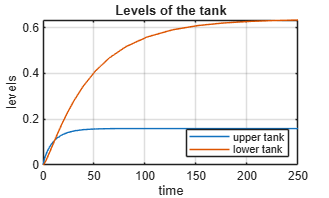

% Simulation
x0=[0 0]'; t0=0; tf=250;
[t,x]=ode23(@(t,x) tank1(t,x,beta1rel,gamma1rel,beta2rel,gamma2rel,u1),[t0 tf],x0);
plot(t,x),grid
title('Levels of the tank')
xlabel('time'); ylabel('levels')
legend('upper tank','lower tank','location','southeast')

As an example the parameters of a real system are: 

$h_{1\max } =h_{2\max } =2\;m$;  $u_{\max } =0\ldotp 01\frac{{\;\;m}^3 }{\sec }$; $A_1 =A_2 =492\ldotp 6\;\ldotp {10}^{-4} {\;m}^2$; $\textrm{a1}=0\ldotp 001{\;m}^2$; $\textrm{a2}=0\ldotp 0005{\;m}^2$; $\mu =1$.

Another example is given in the commented parameters.

The static characteristics can be calculated running the program above for different relative input flows. 

Explore the static characteristics of the model. Change the input flow in the upper tank and look at the steady values of the levels of the upper and the lower tank. The results are 

input flow        level of upper tank     level of the lower tank

0.1                        0.025                            0.102

0.15                      0.057                            0.229

0.2                        0.102                            0.406

0.25                      0.159                            0.63 

0.3                        0.203                            0.904

For higher input flows the water in the lower tank would overflow.

Plot the static characteristics. Fig. 2. and Fig. 3. show the static characteristics for the two considered cases.

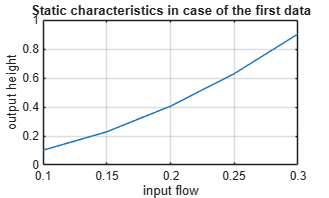

inp=[0.1 0.15 0.2 0.25 0.3]; out=[0.102 0.229 0.406 0.63 0.904];
plot(inp,out),grid
xlabel('input flow')
ylabel('output height')
title('Static characteristics in case of the first data')

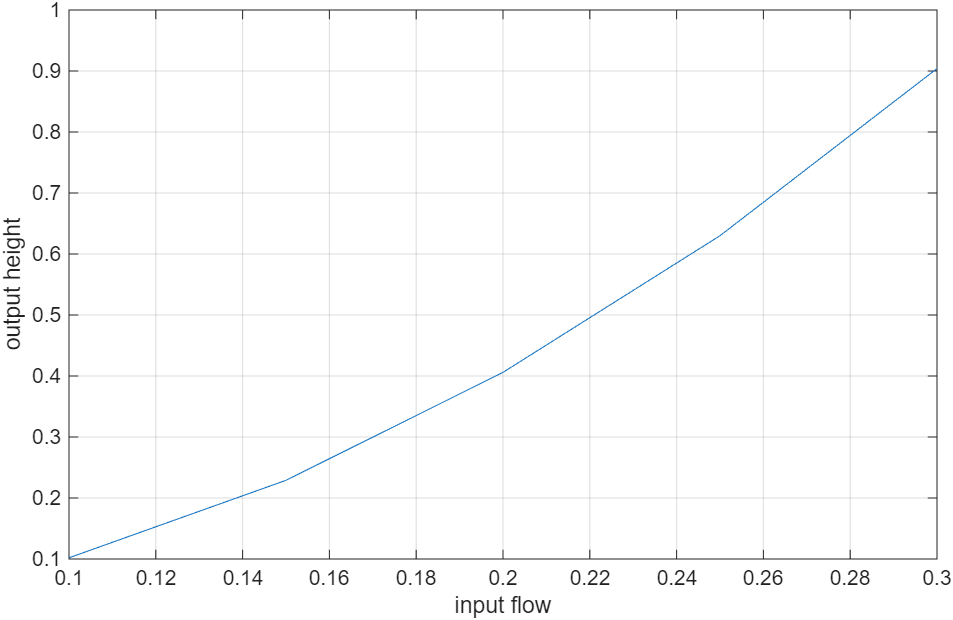

Figure 2. Static characteristics in case of the first data

With the commented parameters:

input flow        level of upper tank     level of the lower tank

0.1                        0.004                            0.016

0.2                        0.016                            0.068

0.25                      0.026                            0.106

0.3                        0.038                            0.15 

0.4                        0.068                            0.27

0.5                        0.106                            0.424

0.6                        0.152                            0.6

0.7                        0.208                            0.832

0.8                        0.27                              1.087

Plot the static characteristics.

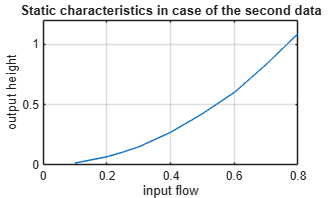

inp=[0.1 0.2 0.25 0.3 0.4 0.5 0.6 0.7 0.8]; out=[0.016 0.068 0.106 0.15 0.27 0.424 0.6 0.832 1.087];
plot(inp,out),grid 
xlabel('input flow')
ylabel('output height')
title('Static characteristics in case of the second data')

  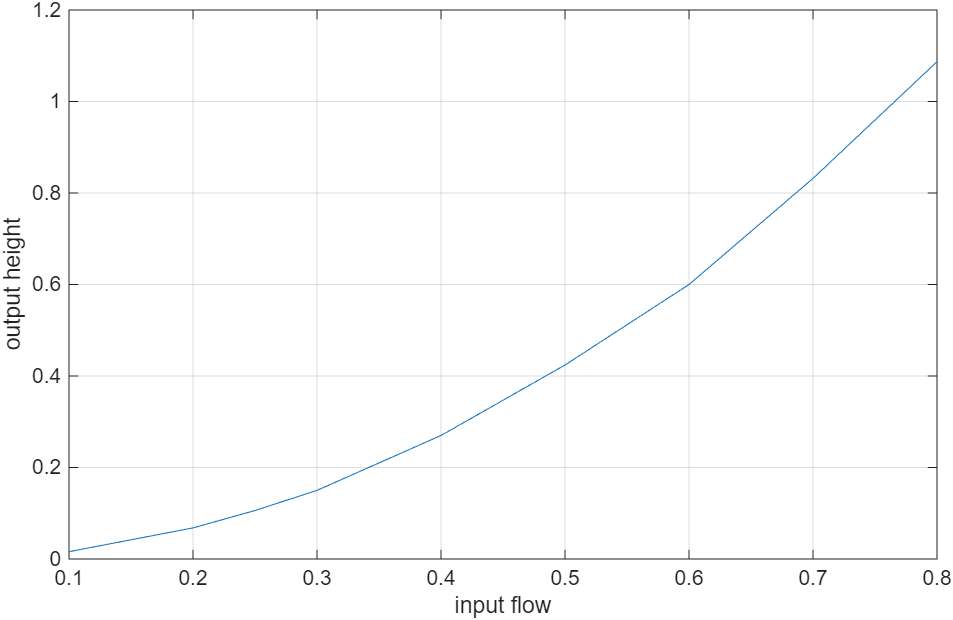

Figure 3. Static characteristics in case of the second data

## 6. Simulink model of the two tank system

The block diagram of the simulink model of the system is given in Fig. 4.

      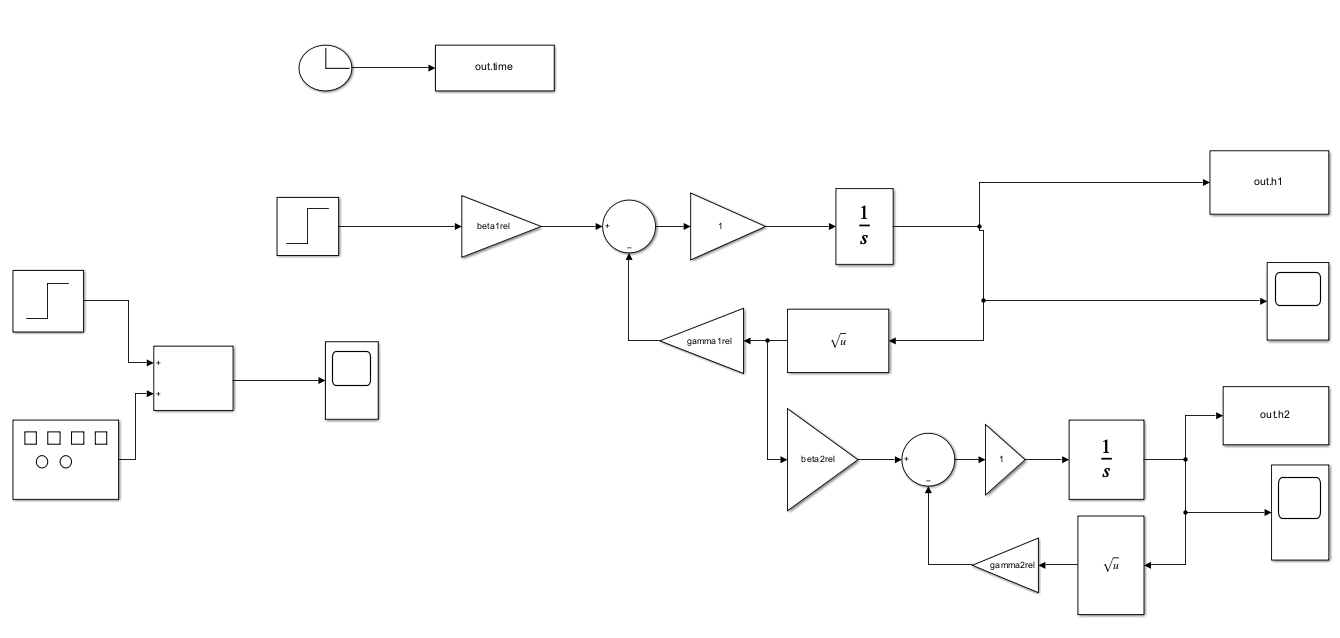

Figure 4. Block diagram of the two tank system

The name of the simulink model which is available from your sublibrary is **tankmodel_nonlinear_control101.slx**. 

The integrators are limited integrators, their upper value is restricted in 1 and lower value in 0.

Let us simulate the output for a step input of 0.25. It is seen that the output is about 0.63, which corresponds to the static characteristics. 

It is possible to change the input for a train of rectangular impulses around a working point to see the behaviour around the working point.

The simulink program can be run also from the matlab environment as shown in the program below.

disp('***********');

***********


disp('Section 6 below');

Section 6 below


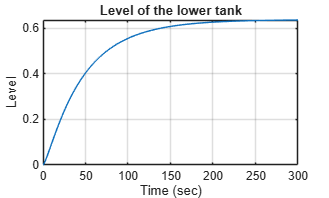


% Run the simulink model and extract the data
%Parameters
% beta1rel=0.1015;
% gamma1rel=0.0636;
% beta2rel=0.0636;
% gamma2rel=0.0318;
Data=sim('tankmodel_nonlinear_control101');
h1=Data.h1;
h2=Data.h2;
t=Data.tout;
u=Data.u;

% Plotting
plot(t,h2),grid
xlabel('Time (sec)')
ylabel('Level')
title('Level of the lower tank')

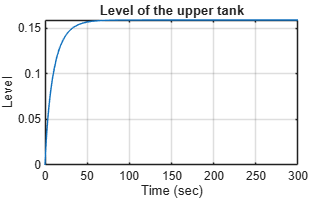

plot(t,h1),grid
xlabel('Time (sec)')
ylabel('Level')
title('Level of the upper tank')

Beyond input flow of value 0.3 the lower tank would overflow, but as limited integrator is used, this will not occur.

## 7. Calculation of the parameters of the linearised model

It is seen that for the first case two linear sections of the characteristics can be chosen. Around input flow 0.15 in the area from 0.1 till 0.2, and around 0.25 in the area from 0.2 till 0.3. Above this input flow the lower tank would overflow.

The linearised models in these two sections can be approximated by second order lag elements with gains, which can be calculated from the static characteristics as (0.406-0.102)/0.1=3.04 and (0.904-0.406)/0.1=4.98, respectively. The time constants can be calculated according to point 4. For small changes with the above data the working points are obtained as h10rel=0.1593 and h20rel=0.6371, and the transfer function for the change around the second working point is 


$$\frac{\Delta h_2 \left(s\right)}{\Delta u\left(s\right)}=\frac{\frac{\delta_{2\textrm{rel}} *\beta_{1\textrm{rel}} }{\alpha_{2\textrm{rel}} *\alpha_{1\textrm{rel}} }}{\left(1+s\frac{1}{\alpha_{1\textrm{rel}} }\right)\left(1+s\frac{1}{\alpha_{2\textrm{rel}} }\right)}=\frac{4\ldotp 98}{\left(1+\textrm{s12}\ldotp 55\right)\left(1+\textrm{s50}\ldotp 25\right)}$$


For the second case four working points can be chosen according to the static characteristics, around input flow 0.2  between 0.1 and 0.3, around input flow 0.4 between 0.3 and 0.5, around input flow 0.5 between 0.4 and 0.6, and around input flow 0.7 between 0.6 and 0.75.

Function **workptransf.m (**subfunction in section 9 below**) **calculates the working points, the levels in the upper and lower tanks for the nominal u0 input flow, and also calculates the gain K and the time constants T1 and T2 for the linearised second order lag element for small changes around the working point.

For example for the first case for u0=0.25

u0=0.25;
[h10rel,h20rel,K,T1,T2]=workptransf(u0,beta1rel,beta2rel,gamma1rel,gamma2rel)

h10rel = 0.1593

h20rel = 0.6371

K = 5.0968

T1 = 12.5535

T2 = 50.2141

alfa1rel=gamma1rel/(2*sqrt(h10rel))

alfa1rel = 0.0797

alfa2rel=gamma2rel/(2*sqrt(h20rel))

alfa2rel = 0.0199

delta2rel=beta2rel/(2*sqrt(h10rel))

delta2rel = 0.0797

The obtained values are close to the values of the transfer function above, the gain is K=5.096, which is close to the value obtained from the static characteristics.

*Student task:* Calculate the transfer functions around working point u0=0.15 and also for the four working points in the second example. 

## 8. PI(D) control of the two tank system

For small changes around the working points the controller can be designed considering this linearised process model.

The water is flowing into the upper tank through a control valve. The input flow is measured by a rotameter. The water is flowing from the upper tank to the lower tank. The outlet flow in both tanks can be set by a tap. The levels in both tanks are measured. The level of the lower tank is controlled by setting the position of the control valve, and thus the inlet flow of the upper tank through a PI(D) controller.

Fig. 5. shows the block diagram of the control system. G denotes the transfer function of the tank system, M denotes the controller which can be a PI algorithm. r is the reference signal describing the desired level in the lower tank. F can be a filter. Input and output disturbances and also measurement noise can be considered. 

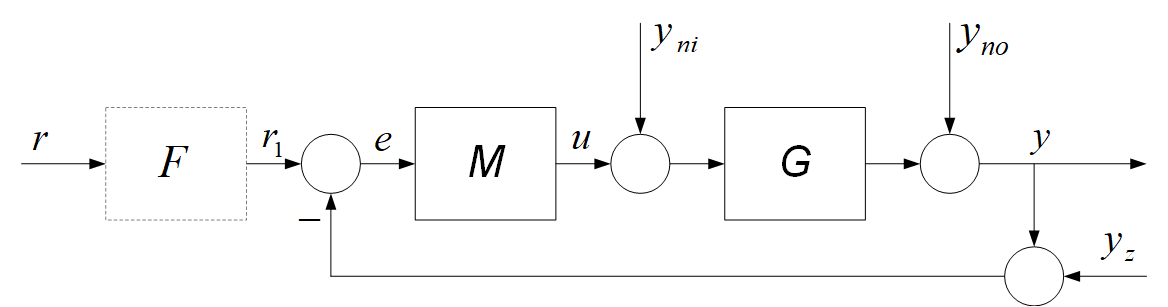

Figure 5. Feedback control structure

As the linearised model of the tank is a second order lag element, PI or PID controller can be used whose parameters depend on the working points. 

The transfer function of the controller is


$$M\left(s\right)=K_c \left(1+\frac{1}{sT_I }+\frac{sT_D }{1+sT_a }\right)$$


The parameters of the controller can be designed using e.g. pole cancellation technique and ensuring about 60 degrees for the phase margin. 

Generally PI control can fulfill the requirements. D effect can be used to accelerate the control behaviour.

The modified transfer function of the controller using pole cancellation is given by 


$$M_1 \left(s\right)=K_c \left(\frac{1+sT_I }{sT_I }\;\frac{1+sT_D }{1+sT_a }\right)$$


The simulink diagram using the linearised model of the tank system is shown on Fig. 6. The model is built based on the state equations above which is valid around the working point. The name of the simulink file is **tankcontrol_linearised_model_PI_controller_control101.slx**

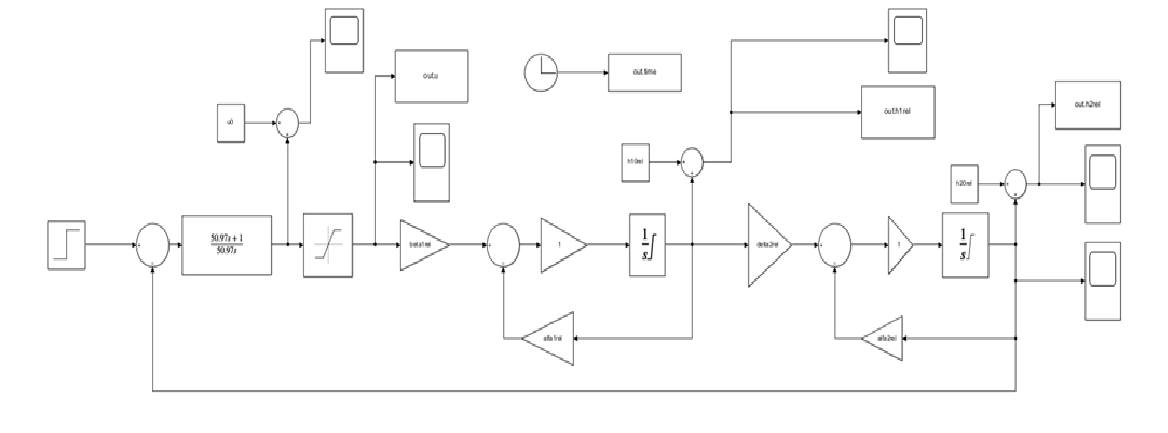

Figure 6. Simulink diagram of PI control of the linearised two tank system 

The initial conditions of the integrators are set to zero, the working point values are added to them (h10rel, h20rel), and also u0 is added to the control signal. The reference value is set to 0.3, this is the change around the working point of the lower tank.

The PI controller is designed according to pole cancellation technique and its transfer function is 


$$M\left(s\right)=\frac{1+50\ldotp 97s}{50\ldotp 97s}$$


The simulink model can be run also from this mlx file as shown below.

disp('***********');

***********


disp('Section 8 below');

Section 8 below


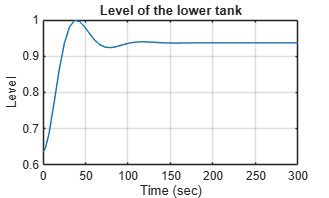


% Run the simulink model and extract the data
% Parameters
% beta1rel=0.1015;
% gamma1rel=0.0636;
% beta2rel=0.0636;
% gamma2rel=0.0318;
Data=sim('tankcontrol_linearised_model_PI_controller_control101');
% 
Data.h1rel;
h1rel=Data.h1rel;
h2rel=Data.h2rel;
t=Data.tout;
u=Data.u;

% Plotting
plot(t,h2rel),grid
xlabel('Time (sec)')
ylabel('Level')
title('Level of the lower tank')

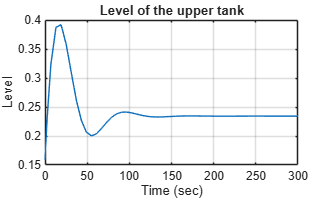

plot(t,h1rel),grid
xlabel('Time (sec)')
ylabel('Level')
title('Level of the upper tank')

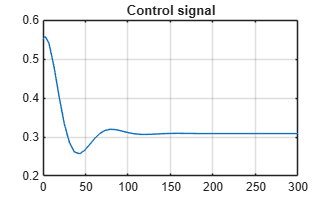

plot(t,u+u0),grid
title('Control signal')

Student task: Check the control performance using different PI controller.

The **TwoTanks.mlapp** file demonstrates also graphically the behaviour of the two tank system and its control. Here the effect of the change of the parameters and setting of the controller is insightful. Description of the file is given in detail, see **TwoTanks.docx**.

Let us check the behaviour of the control system when the two tank system is given by the nonlinear equations of its model. The simulink diagram is shown on Fig.7. 

The name of the slx file is **tankcontrol_nonlin_model_PI_controller_control101.slx.**

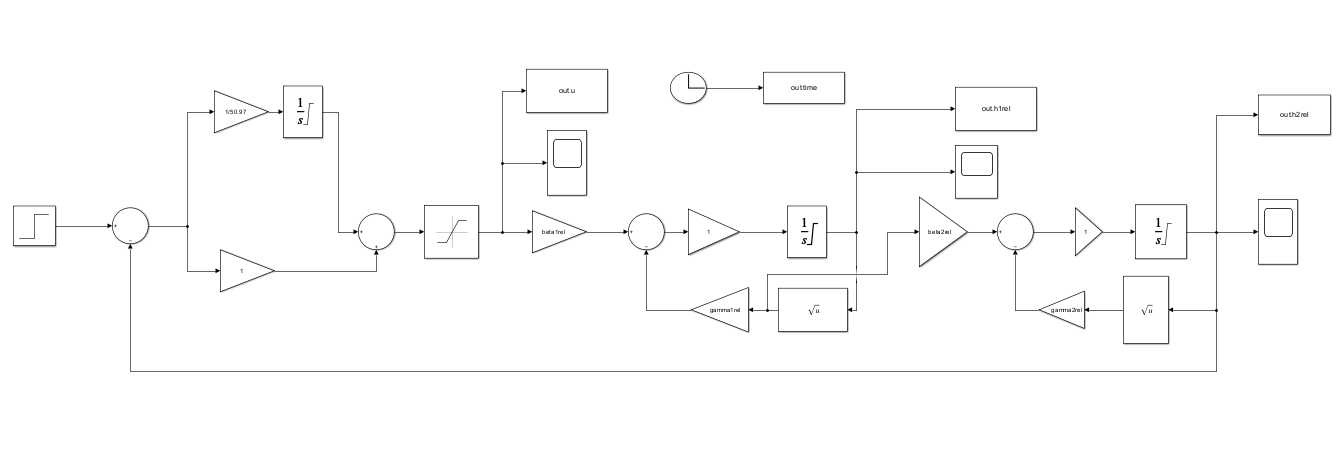

Figure 7. Simulink diagram of PI control of the nonlinear two tank system 

The initial conditions of the integrators are given as h10rel and h20rel.

The initial condition of the integrator in the PI controller is set to u0, so the control process starts from the working point. The small change in the linearity region around the working point is given by the reference value, which changes from 0.6371 to 0.9371.

The simulink model can be run also from this mlx file as shown below.

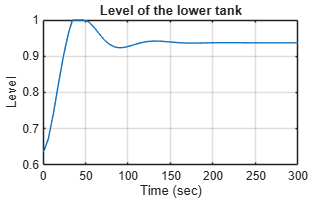

% Run the simulink model and extract the data
%Parameters
% beta1rel=0.1015;
% gamma1rel=0.0636;
% beta2rel=0.0636;
% gamma2rel=0.0318;
Data=sim('tankcontrol_nonlin_model_PI_controller_control101');
% 
Data.h1rel;
h1rel=Data.h1rel;
h2rel=Data.h2rel;
t=Data.tout;
u=Data.u;
% Plotting
plot(t,h2rel),grid
xlabel('Time (sec)')
ylabel('Level')
title('Level of the lower tank')

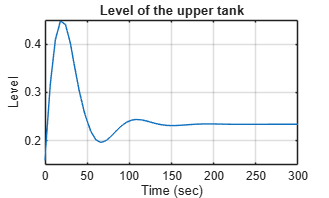

plot(t,h1rel),grid
xlabel('Time (sec)')
ylabel('Level')
title('Level of the upper tank')

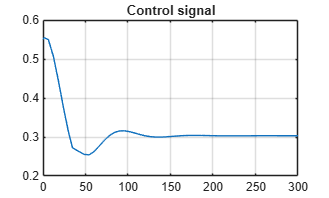

plot(t,u),grid
title('Control signal')

*Student task:* Check the performance with a different PI controller. Design PID controller to accelerate the behaviour.

Choose other working points and design the controller. Check the behaviour of the control system.

Compare the behaviour of the control system analysing it by the nonlinear and by the linearised system model.

## 9 Useful sub-functions

function [h10rel,h20rel,K,T1,T2]=workptransf(u0,beta1rel,beta2rel,gamma1rel,gamma2rel)
%calculates the working points
h10rel=(beta1rel*u0/gamma1rel)^2;
h20rel=((beta2rel*sqrt(h10rel))/gamma2rel)^2;
alfa1rel=gamma1rel/(2*sqrt(h10rel));
alfa2rel=gamma2rel/(2*sqrt(h20rel));
delta2rel=beta2rel/(2*sqrt(h10rel));
K=(beta1rel*delta2rel)/(alfa1rel*alfa2rel);
T1=1/alfa1rel;
T2=1/alfa2rel;
end

function [beta1rel,gamma1rel,beta2rel,gamma2rel] = tankdata(umax,h1max,h2max,A1,A2,a1,a2,mu)
% Gives the parameters of the nonlinear two tank system with relative
% variables
%beta1=0.0033; gamma1=0.003;beta2=0.003; gamma2=0.00378; u1=1;
k1=mu*a1*sqrt(2*9.81);
k2 = mu*a2*sqrt(2*9.81);
beta1rel = umax/(A1*h1max);
gamma1rel = k1/(A1*sqrt(h1max));
beta2rel = (k1*sqrt(h1max))/(A2*h2max);
gamma2rel =k2/(A2*sqrt(h2max));
end

function xtank1=tank1(t,x,beta1rel,gamma1rel,beta2rel,gamma2rel,u1)
%Example with data from measurement
%beta1=0.0033; gamma1=0.003;beta2=0.003; gamma2=0.00378; u1=0.25;
%
% Alternative data
% A1=492.6/100/100; % m2 (diameter of the cilinder d=25 cm)
% A2=492.6/100/100; % m2 (diameter of the cilinder d=25 cm)
% 
% a1=10/100/100;       % m2 radius of the outlet tube r=1.8cm
% a2=a1/2.0;           % m2 radius of the outlet tube r=1.25cm
% 
% h1max=2;             % m
% h2max=2;             % m
% 
% u1max = 0.01;        % m3/s = 10 liter/s
% u1rel=0.25;          % --> u1=0.0025  m3/s = 2.5 liter/s
% 
% mu=1;                % viscosity of water
% 
% beta1=0.1015; gamma1=0.0636;beta2=0.0636; gamma2=0.0318; 
xtank1(1)=beta1rel*u1-gamma1rel*sqrt(x(1));
xtank1(2)=beta2rel*sqrt(x(1))-gamma2rel*sqrt(x(2));
xtank1=[xtank1(1) xtank1(2)]';
end